# CSG primitives and methods usage example

#### Common setup for all examples

ex_setup

Setup complete


#### Start timer

tic

#### Povlab object

pl = povlab( povray_version,...
             povray_path, ...
             povray_out_dir);

#### Scene

pl.scene_begin('scene_file', 'csg.pov', 'image_file', 'csg.png');
    pl.include("shapes");
    
    pl.global_settings("assumed_gamma 1");

    % Camera
    pl.camera('angle', 35, 'location', [28 15 10], 'look_at', [0 6 3.5], 'type', 'perspective');
    
    % Lights
    pl.light('location', [100 100 300], 'color', [0.4 0.4 0.4], 'shadowless', false);
    pl.light('location', [10 4 3], 'color', [0.2 0.2 0.2], 'shadowless', true);
    
    % Walls
    tex_plane  = pl.declare("tex_plane", pl.texture('pigment_odd', [1.5 1.5 1.5], 'pigment_even', [0.1 0.1 0.1]));    
    pl.plane('normal', [1,0,0], 'texture', 'tex_plane', 'translate', [-10 0 1]);
    pl.plane('normal', [0,0,1], 'texture', tex_plane');
    
    % Textures
    tex_red   = pl.declare("tex_red",   pl.texture('pigment', [1 0 0]));
    tex_green = pl.declare("tex_green", pl.texture('pigment', [0 1 0]));
    tex_blue  = pl.declare("tex_blue",  pl.texture('pigment', [0 0 1]));
    tex_pink  = pl.declare("tex_pink",  pl.texture('pigment', [8 2 3]));
    
    % Objects
    pl.difference_begin();
        pl.sphere('position', [1 1 1], 'radius', 2, 'texture', tex_green, 'translate', [0 1 0]);
        pl.union_begin();
              pl.sphere('position', [2 1 1.5], 'radius', 0.7, 'texture', tex_red);
              pl.sphere('position', [2 3 1],   'radius', 0.8, 'texture', tex_blue);
              pl.sphere('position', [1 2 3],   'radius', 1.1, 'texture', tex_pink);
         pl.union_end('translate', [0.3 0.3 0.3]);
    pl.difference_end('translate', [0 8.5 5],  'rotate', [0 10 0], 'scale', [1.15 1.15 1.15]);
    
    pl.difference_begin();
        pl.cone('base_point', [1 1 0], 'base_radius', 4, 'cap_point', [1 1 6], 'cap_radius', 1.5, 'texture', tex_pink);
        pl.cylinder('base_point', [1 1 -1], 'cap_point', [1 1 8],  'radius', 1, 'texture', tex_red);
        pl.cylinder('base_point', [1 1 -1], 'cap_point', [1 1 8],  'radius', 1, 'texture', tex_blue,  'translate', [3.5 0 0]);
        pl.cylinder('base_point', [1 1 -1], 'cap_point', [1 1 8],  'radius', 1, 'texture', tex_green, 'translate', [2.5 2.5 0]);
        pl.cylinder('base_point', [0 0 -8], 'cap_point', [0 0 10], 'radius', 1, 'texture', tex_green, 'translate', [0 2 4.5], 'rotate', [90 90 90]);    
    pl.difference_end('translate', [0 1.8 0], 'scale', [1.1 1.1 1.1]);

pl.scene_end();

#### Render and display

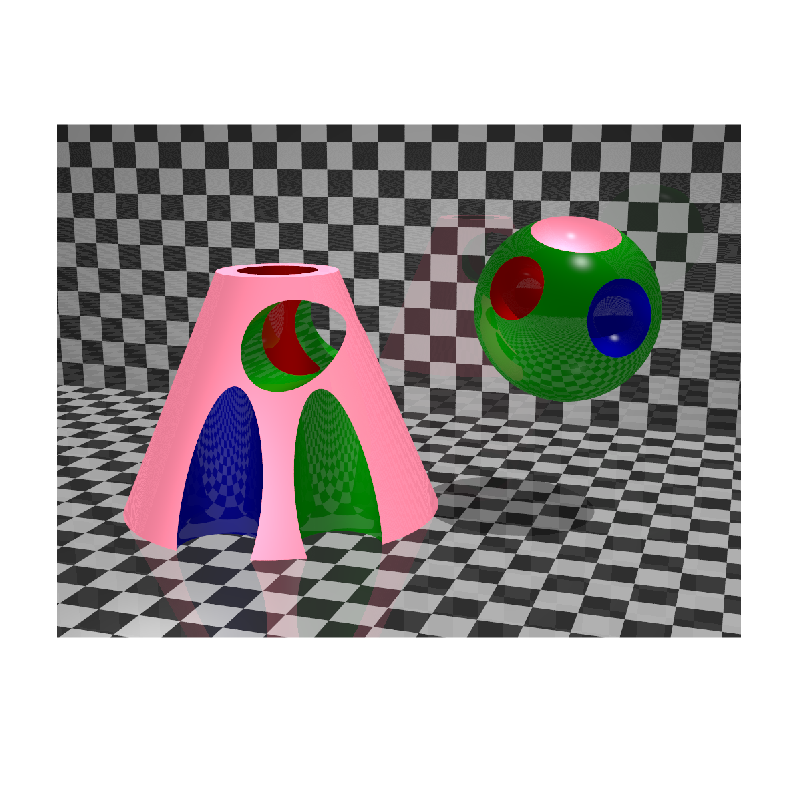

img = pl.render();
imshow(img);

#### Elapsed time

toc

Elapsed time is 5.094474 seconds.
